# MVO-31: LAB02 - Q2

Considerações iniciais:

- Limite de altura: $300\,m$;

- Altitude operacional: $1500\,ft = 457.2\,m$;

- Velocidade máxima: $270\,kt = 138.9\,m/s$

- $n_{max} = 5g$;

- Fator de carga constante na recuperação;

- Ângulo de lançamento: $-25°$.

1a)


$$n_x = \sin(x) - \frac{v'}{g}%$$



$$n_z = \cos(x) + \frac{v^2}{rg}$$



$$r = \frac{v^2}{g(n_z - \cos(x))}$$


1b)

O raio de recuperação crítico é obtido quando utiliza-se o valor de $n_z = 5$ na expressão encontrada acima, pois um raio menor implicaria um fator de carga maior do que o limite do ensaio.

1c)

Gerando o gráfico pedido pelo enunciado para uma velocidade constante e igual à velocidade máxima de $138.9\,m/s$:

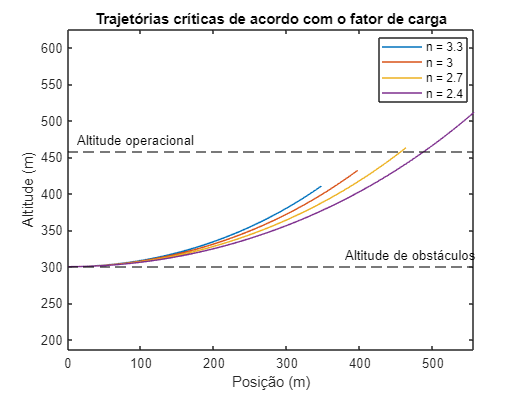

v = 138.9;
launch_angle = 25*pi/180;
theta = linspace(launch_angle,0,100);

for n = [3.3 3 2.7 2.4]
    r_theta = r(theta,v,n);

    x = r_theta.*sin(theta);
    y = r(0,v,n) - r_theta.*cos(theta)+300;

    plot(x,y)
    hold on
end

lim_y = max(y)*1.05;
lim_x = max(x)*1.05;
axis equal
yline(300,'k--')
text(0.65*lim_x,300+lim_y*0.03,'Altitude de obstáculos')
yline(457.2,'k--')
text(0.02*lim_x,457.2+lim_y*0.03,'Altitude operacional')
legend("n = 3.3", "n = 3", "n = 2.7", ...
    "n = 2.4", "","",...
    'Location','best')
ylabel('Altitude (m)')
xlabel('Posição (m)')
title('Trajetórias críticas de acordo com o fator de carga')

hold off

1d)

O fator de carga máximo $n_{max}$ para essa manobra ser segura é tal que a altitude a $25º$ seja igual à a altitude operacional de $457.2\,m$.    

for n = linspace(2.7,3,30000)
    if abs(r(0,v,n) - r(launch_angle,v,n)*cos(launch_angle)+300-457.2) < 0.001
        n_max = n
    end
end

n_max = 2.7488

function radius = r(angle,vel,n_z)
    g = 9.81;
    radius = vel^2./(g*(n_z-cos(angle)));
end